Plot final loads (P*n*** &** p*t*) along the blade. (at nt_max)

disp('Plot final loads (Pn & pt) along the blade. (at nt_max)')

Plot final loads (Pn & pt) along the blade. (at nt_max)


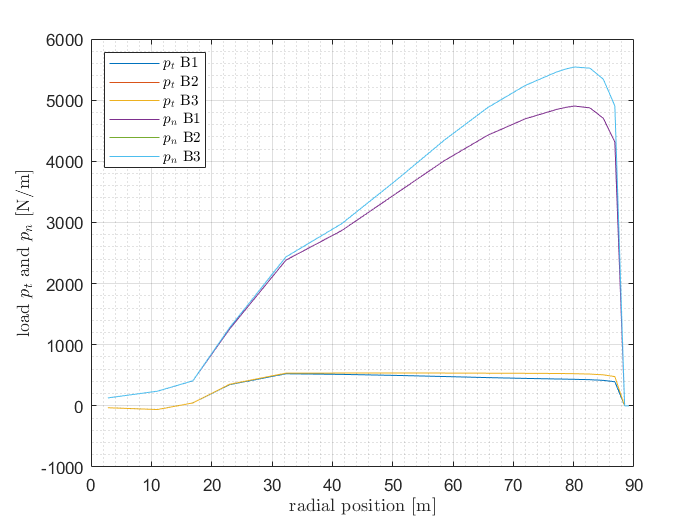

plot(r,pt(:,1,nt_max),r,pt(:,2,nt_max),r,pt(:,3,nt_max),r,pn(:,1,nt_max),r,pn(:,2,nt_max),r,pn(:,3,nt_max))
grid on; grid minor
legend({'$p_t$ B1','$p_t$ B2','$p_t$ B3','$p_n$ B1','$p_n$ B2','$p_n$ B3'},"Interpreter","latex","Location","northwest")
xlabel('radial position [m]',"Interpreter","latex")
ylabel('load $p_t$ and $p_n$ [N/m]',"Interpreter","latex")

if nu > 0
    plot(r,pt(:,1,ceil(pi/(4*omega(1)*dt))), ...
        r,pt(:,1,ceil(pi/(2*omega(1)*dt))),...
        r,pt(:,1,ceil(3*pi/(4*omega(1)*dt))),...
        r,pt(:,1,ceil(pi/(omega(1)*dt))));
end

Plot variation in time of the loads for a given r (blade element)

disp('Plot variation in time of the loads for a given r (blade element)')

Plot variation in time of the loads for a given r (blade element)


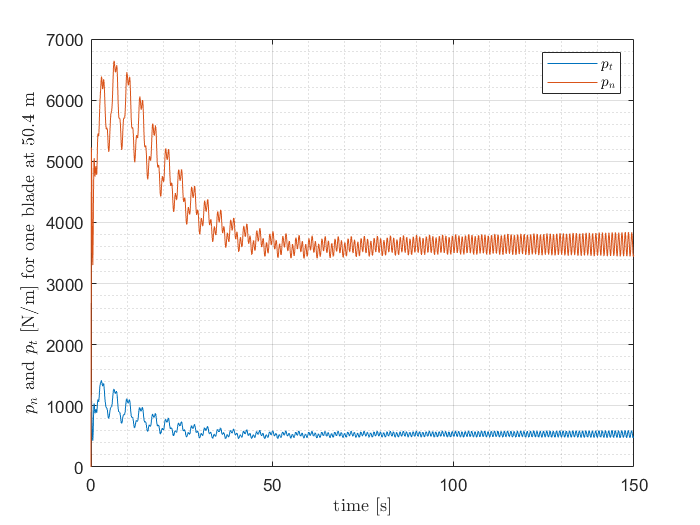

pt_1 = zeros(nt_max,1);
pn_1 = zeros(nt_max,1);
for i=1:nt_max
    pt_1(i) = pt(7,1,i); %Vector for one blade in time
    pn_1(i) = pn(7,1,i); %Vector for one blade in time
end
plot(time,pt_1,time,pn_1)
xlabel('time [s]',"Interpreter","latex")
ylabel('$p_n$ and $p_t$ [N/m] for one blade at 50.4 m',"Interpreter","latex")
legend({'$p_t$','$p_n$'},"Interpreter","latex")
grid on; grid minor;

Induced wind in z (Wz) for the first 5 time steps for blade 1.

disp('Induced wind in z (Wz) for the first 5 time steps for blade 1.')

Induced wind in z (Wz) for the first 5 time steps for blade 1.


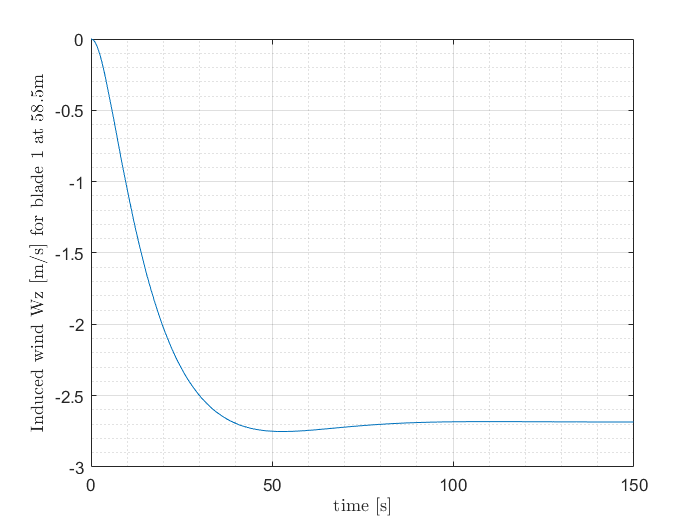

Wz_1=zeros(nt_max,1);
for i=1:nt_max
    Wz_1(i) = Wz(8,1,i); %Vector for one blade in time
end

plot(time(1:nt_max),Wz_1(1:nt_max))
grid on; grid minor;
xlabel('time [s]',"Interpreter","latex")
ylabel('Induced wind Wz [m/s] for blade 1 at 58.5m',"Interpreter","latex")

Variation of Power in time.

disp('Variation of Power in time.')

Variation of Power in time.


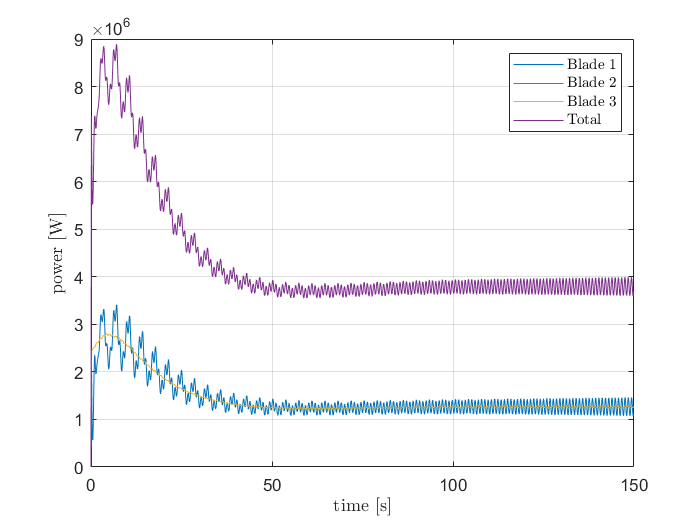

plot(time,P1,time,P2,time,P3,time,P_total)
grid on %; grid minor;
legend({'Blade 1','Blade 2','Blade 3','Total'},"Interpreter","latex","Location","best")
xlabel('time [s]',"Interpreter","latex")
ylabel('power [W]',"Interpreter","latex")


Pave = mean(P_total(5:end));
Pmax = max(P_total(5:end));
disp(['Average power: '  num2str(Pave/1e6) ' MW'])

Average power: 4.3418 MW


disp(['Max power: '  num2str(Pmax/1e6) ' MW'])

Max power: 8.8868 MW


Variation of Thrust in time.

disp('Variation of Thrust in time.')

Variation of Thrust in time.


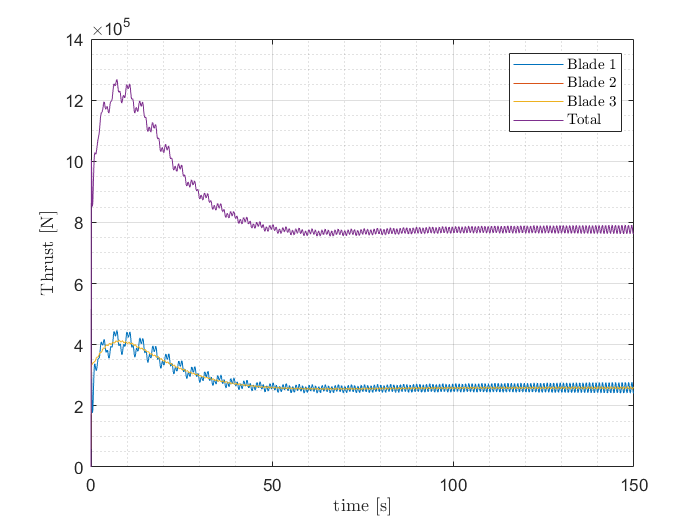

plot(time,T1,time,T2,time,T3,time,T1+T2+T3)
grid on; grid minor;
legend({'Blade 1','Blade 2','Blade 3','Total'},"Interpreter","latex","Location","best")
xlabel('time [s]',"Interpreter","latex")
ylabel('Thrust [N]',"Interpreter","latex")


Tave = mean(T_total(5:end));
Tmax = max(T_total(5:end));
disp(['Average thrust: '  num2str(Tave/1e3) ' kN'])

Average thrust: 843.1863 kN


disp(['Max thrust: '  num2str(Tmax/1e3) ' kN'])

Max thrust: 1267.8524 kN
